MECE6397: Learning-Based Control                               

# Homework 1: Feedback Fundamentals

Lecturer: Marzia Cescon

In the field of control, the concepts of **model** and **feedback **are cornerstones. In this homework, we will review these two fundamental principles with examples.

## 1. System Modeling

A model is a mathematical representation of a system used to describe its dynamical behavior. Typically, the model is used to analyze the system it describes with simulations predicting its behavior and properties. Depending on the analysis tasks, there may be multiple and equally valid representations of the same system with various degrees of complexity. In this section, we will review two common classes of mathematical models for dynamical systems: ordinary differential equations (ODEs), and difference equations. We will introduce a damped spring-mass system to illustate the ODEs-based model and a predator-prey system to show the difference equation-based model.

### 1.1 Ordinary Differential Equations: Simulation of a Spring-Mass System

Figure 1 illustrates a spring-mass system with a damper. There are two masses, $m_1$and $m_2 \;$, respectively, three springs with spring constants $k_1$, $k_2$, and $k_3$, respectively, and a linear damping element with coefficient of viscous friction $c\ldotp$ To model the system, we use principles from rigid body physics. We model the springs with Hooke's law, $F=k\left(x-x_{\textrm{rest}} \right)$, and assume that the dumper exerts a force proportional to the velocity of the system, $F=\textrm{cv}$. Thus, the system depicted in the figure can be described with the following equations:


$$m_1 \ddot{{\;q}_1 } =k_{2\;} \left(q_2 -q_1 \right)-k_1 q_1$$



$$m_2 \;\ddot{q_2 } =k_{3\;} \left(u-q_2 \right)-k_2 \left(q_2 -q_1 \right)-c\dot{q_2 }$$
 

where $q_1$ and $q_2$ are the positions of the masses, $\dot{q_1 }$ and $\dot{q_2 }$ the velocities, $\ddot{q_1 }$ and $\ddot{q_2 }$ are the accelarations. The position of the spring at the right of the chain, $u\left(t\right),$ represents the external excitation forcing the system.

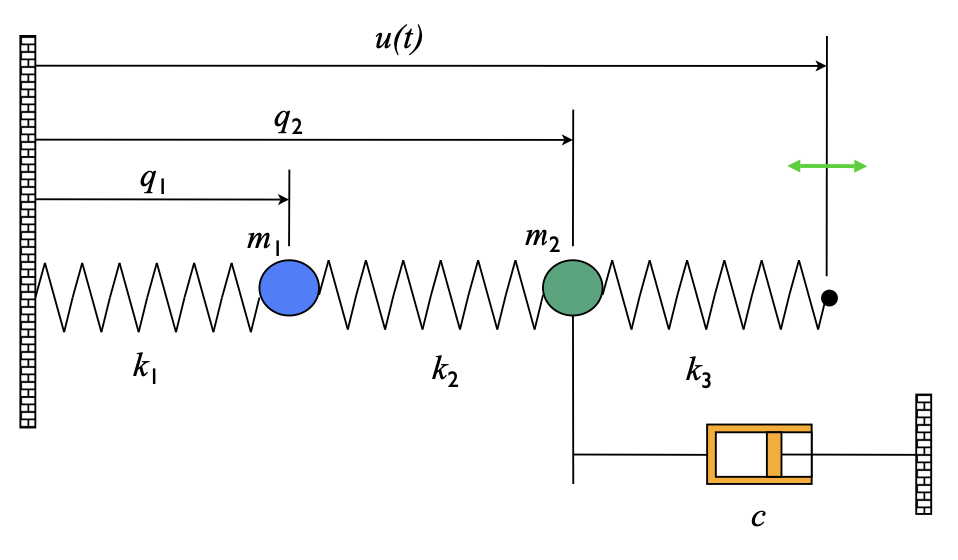

*Figure 1. Spring-mass system with a damper.*

It is possible to convert the model from ODEs form to state-space form, by executing the following steps:

- Construct a vector of the variables that are required to specify the evolution of the system, i.e., $x=\left(q,\dot{q} \right)$

- Write the dynamics as a system of first order differential equations, in the form:

                
$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=f\left(x,u\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\in \;{\mathbb{R}}^n ,u\in {\mathbb{R}}^p \\
y=h\left(x\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\in {\mathbb{R}}^q 
\end{array}$$


This yields the following state-space model for the damped spring-mass system in our example:

                
$$\frac{d}{dt}\left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
\dot{q_1 } \\
\dot{q_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{q_1 } \\
\dot{q_2 } \\
\frac{k_{2\;} }{m}\left(q_2 -q_1 \right)-\frac{k_1 }{m}q_1 \\
\frac{k_{3\;} }{m}\left(u-q_2 \right)-\frac{k_2 }{m}\left(q_2 -q_1 \right)-\frac{c}{m}\dot{q_2 } 
\end{array}\right\rbrack$$



$$y=\left\lbrack \begin{array}{c}
q_1 \\
q_2 
\end{array}\right\rbrack$$


The model is comprised of:

- *state* $x\left(t\right),$which captures the effects of the past and in absence of external excitation determines the future evolution of the system; in our example, position and velocity of each mass: $x\left(t\right)={\left\lbrack \begin{array}{cccc}
q_1 \left(t\right) & q_2 \left(t\right) & {\dot{q} }_1 \left(t\right) & {\dot{q} }_2 \left(t\right)
\end{array}\right\rbrack }^T$

- *input *$u\left(t\right),$ which describes the external excitation; in our example the position of the rightmost spring

- *output *$y\left(t\right),$which describes measured quantities and are function of the state and input; in our example, the measured positions of the masses $y\left(t\right)={\left\lbrack \begin{array}{cc}
q_1 \left(t\right) & q_2 \left(t\right)
\end{array}\right\rbrack }^T$

The [springmass](matlab:open('.\springmass.m')) function implements the model of the dynamics of the damped spring-mass system in state-space form. With this model, we can answer questions such as "How much do masses move as a function of the forcing function?", "What happens if we change values of the masses?". Study the function.

**Task 1.** Force the system with a sinusoid $u\left(t\right)\;=\;A\;\cos \left(\omega t\right)$. Start with values$A=0\ldotp 00315\;m$ and $\omega =0\ldotp 75\;\mathrm{rad}/s$ and experiment with different values of $A$ and ω using the following three trials. Plot the responses after the transients have died out.

- **Trial 1:**

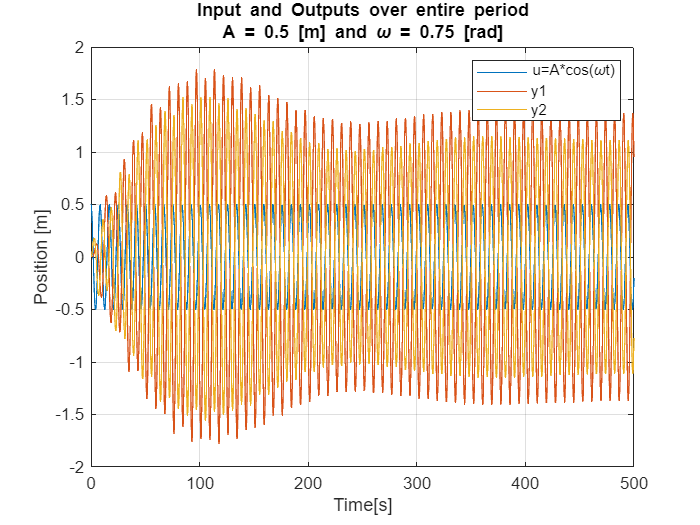

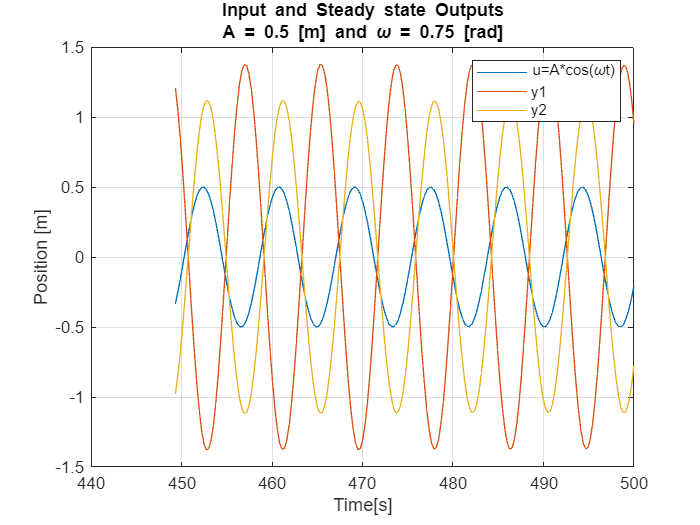

% Spring mass system parameters
m = 250; m1 = m; m2 = m; % masses [kg] (all equal)
k = 50; k1 = k; k2 = k; k3 = k; % spring constants
A = 0.5; omega = 0.75; % forcing function A [m], omega [rad/s]
titl=sprintf('A = %s [m] and \\omega = %s [rad]',num2str(A),num2str(omega));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl); % Uses ode45 to solve the system in the springmass function

- **Trial 2:**

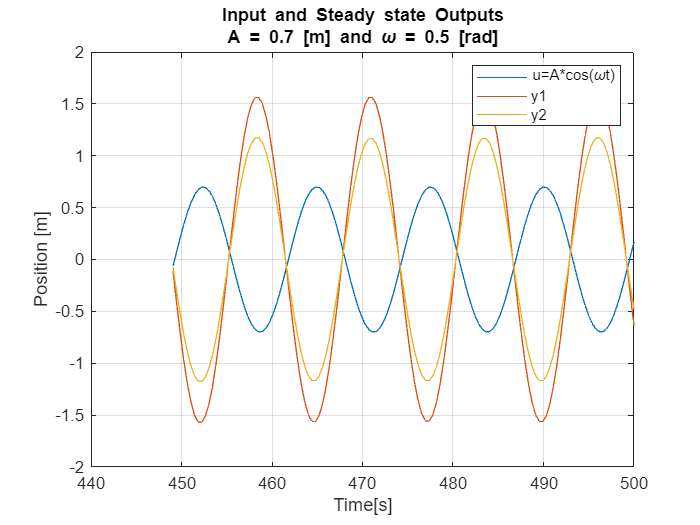

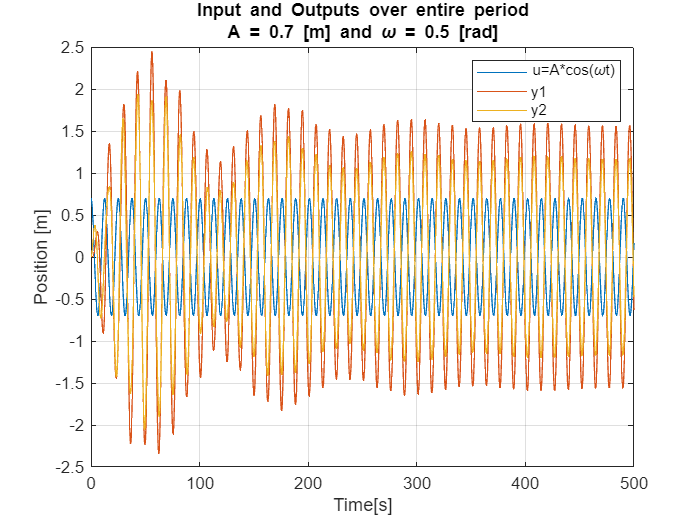

A = 0.7; omega = 0.5; % forcing function
titl=sprintf('A = %s [m] and \\omega = %s [rad]',num2str(A),num2str(omega));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);

- **Trial 3:**

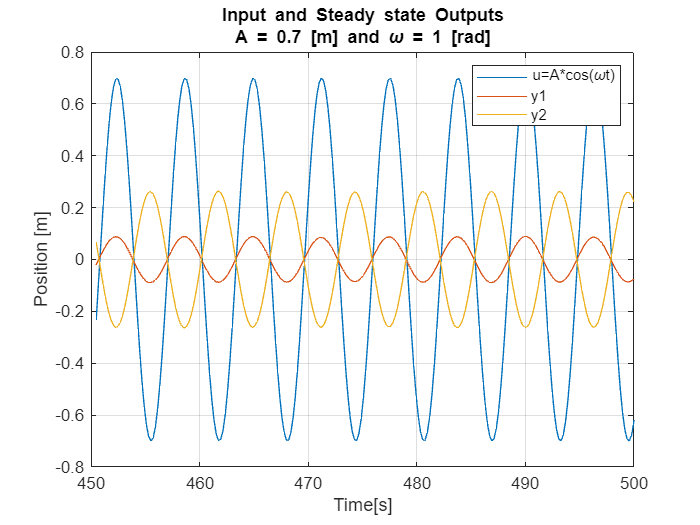

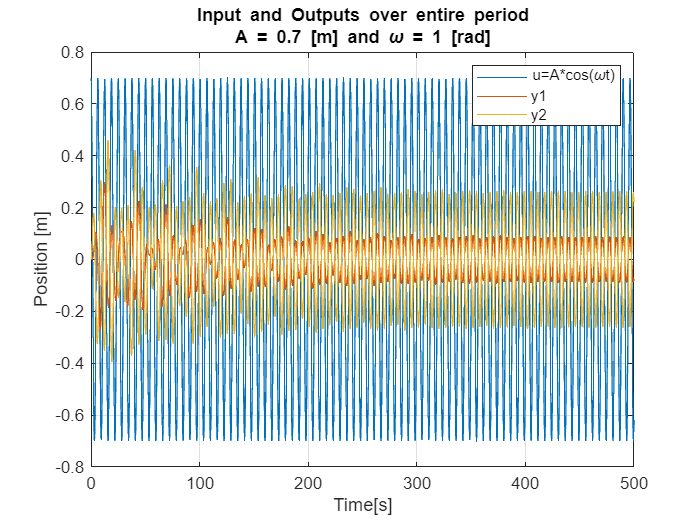

A = 0.7; omega = 1; % forcing function
titl=sprintf('A = %s [m] and \\omega = %s [rad]',num2str(A),num2str(omega));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);

**Task 2.** When the sinusoid is in steady state, compute the relative phase and amplitude of the signals, using simple trigonometry $\left(\sin^2 \left(x\right)+\cos^2 \left(x\right)=1\right)$. The function [relativephaseandamplitude](matlab:open('./relativephaseandamplitude.m')) computes both relative amplitudes and relative phases for the outputs $y_1$ and $y_2$, then plots the computed outputs.

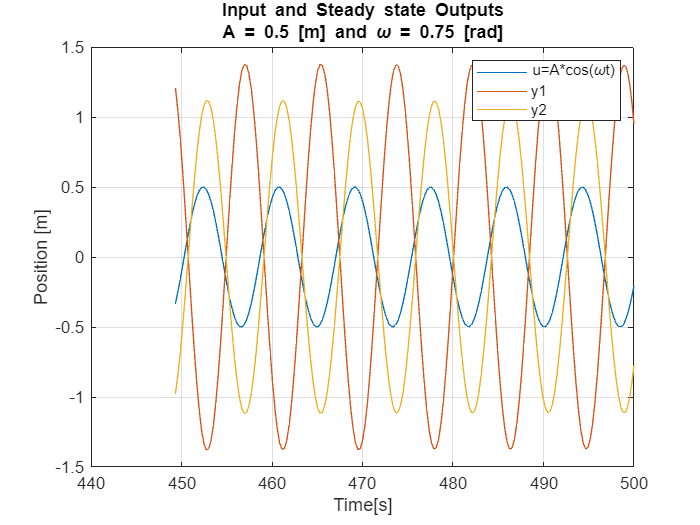

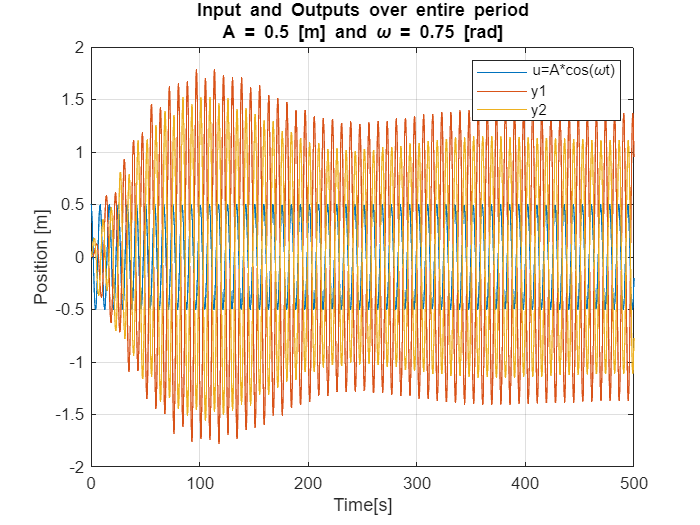

% Spring mass system parameters
m = 250; m1 = m; m2 = m; % masses (all equal)
k = 50; k1 = k; k2 = k; k3 = k; % spring constants
A = 0.5; omega = 0.75; % forcing function (picked one of the trials)
titl=sprintf('A = %s [m] and \\omega = %s [rad]',num2str(A),num2str(omega));
clf
[tend,A,omega,range,y]=springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);


 Relative Amplitude 1 = 1.37671e+00 m 
 Relative Amplitude 2 = 1.11640e+00 m 
 Relative Phase 1 = -336.485 rad/s 
 Relative Phase 2 = -333.34 rad/s
 
 
 Plotting computed outputs...

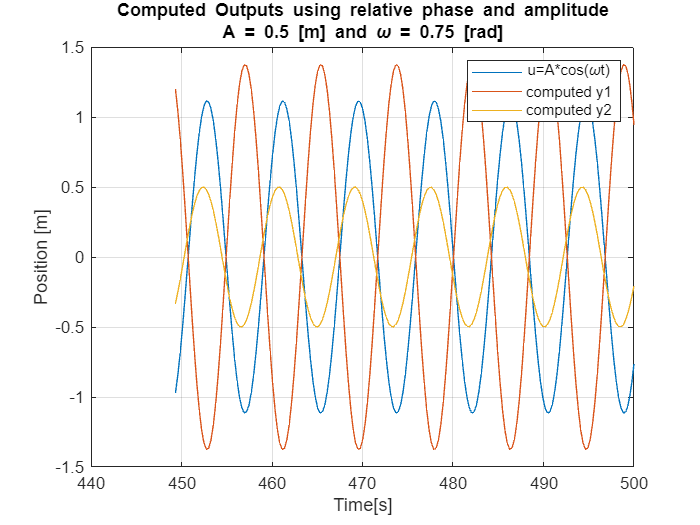

relativephaseandamplitude(tend,A,omega,range,y)

**Task 3.** Now experiment with different values for $m_{1\;}$, $m_2$, $k_1$, $k_2$and $k_3$. Plot the responses.

- **Trial 1:**

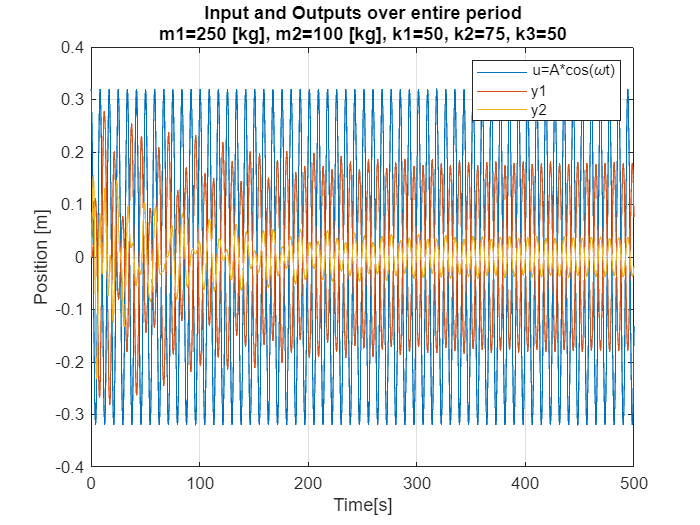

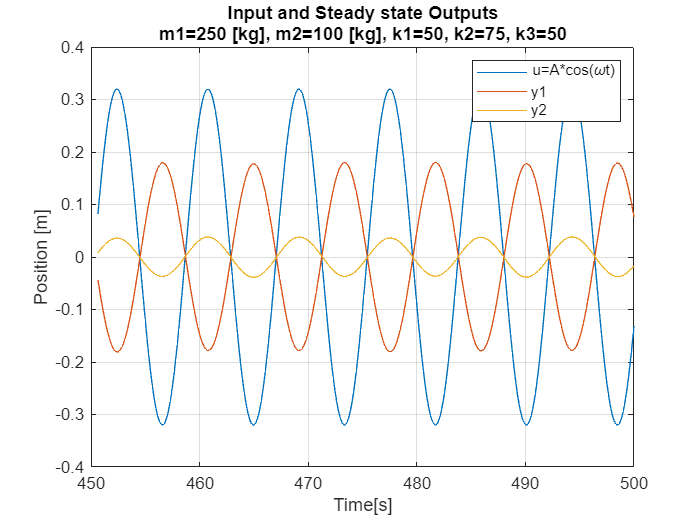

% Spring mass system parameters
m1 = 250; m2 = 100; % masses
k1 = 50; k2 = 75; k3 = 50; % spring constants
A = 0.32; omega = 0.75; % forcing function
titl=sprintf('m1=%s [kg], m2=%s [kg], k1=%s, k2=%s, k3=%s',num2str(m1),num2str(m2),num2str(k1),num2str(k2),num2str(k3));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);

- **Trial 2:**

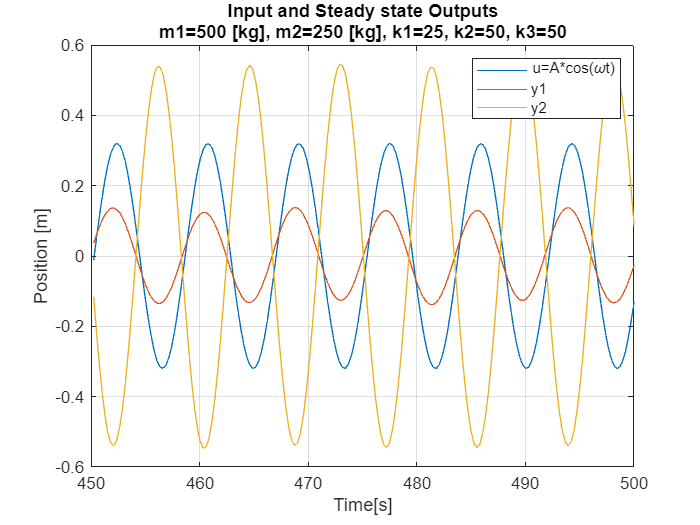

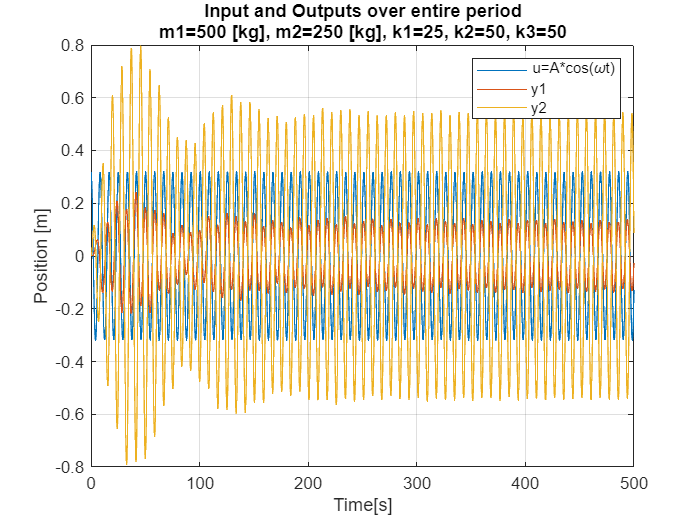

% Spring mass system parameters
m1 = 500; m2 = 250; % masses
k1 = 25; k2 = 50; k3 = 50; % spring constants
A = 0.32; omega = 0.75; % forcing function
titl=sprintf('m1=%s [kg], m2=%s [kg], k1=%s, k2=%s, k3=%s',num2str(m1),num2str(m2),num2str(k1),num2str(k2),num2str(k3));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);

- **Trial 3:**

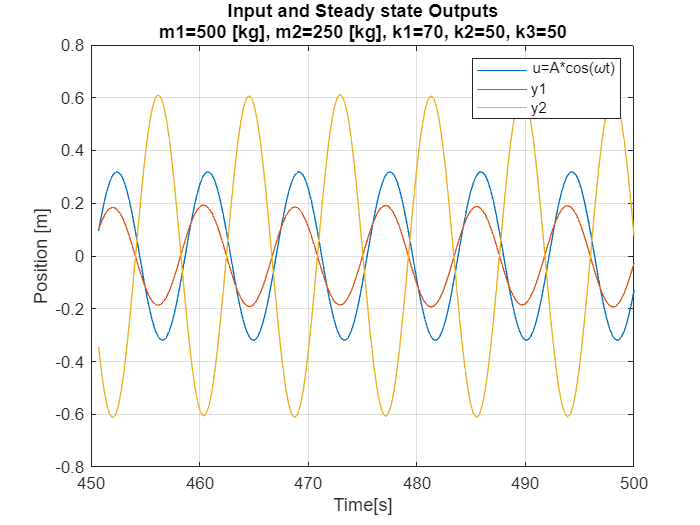

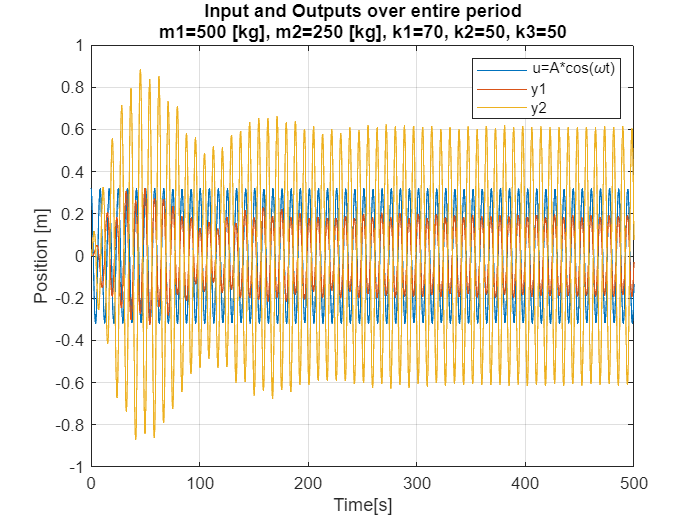

% Spring mass system parameters
m1 = 500; m2 = 250; % masses
k1 = 70; k2 = 50; k3 = 50; % spring constants
A = 0.32; omega = 0.75; % forcing function
titl=sprintf('m1=%s [kg], m2=%s [kg], k1=%s, k2=%s, k3=%s',num2str(m1),num2str(m2),num2str(k1),num2str(k2),num2str(k3));
clf
springmassSolver(A,omega,m1,m2,k1,k2,k3,titl);

The example shows that for the damped spring-mass system the response to a sinusoidal input is a sinusoid at the same frequency of the input, with change in magnitude and shift in phase:


$$u\left(t\right)=A\;\sin \left(\omega t\right)$$



$$y\left(t\right)=g\left(\omega \right)\;\sin \left(\omega t+\phi \left(\omega \right)\right)\;$$


The relationship between gain and phase of a sinusoidal input and the corresponding sinusoidal output is called f*requency response*, and it is described by an object called *transfer function*. More formally, the transfer function for a linear system $\Sigma =\left(A,B,C,D\right)$ is a function $H\left(s\right),$ $s\in \mathbb{C},$ such that $H\left(j\omega \right)$ gives the gain $\left|H\left(j\omega \right)\right|$ and phase $\arg \;H\left(j\omega \right)$ of the response to a sinusoid at frequency $\omega$. $H\left(s\right)$ is given by:


$$H\left(s\right)={C\left(\textrm{sI}-A\right)}^{-1\;} B+D,\;\;\;\;\;s\in \mathbb{C}$$


- Poles (roots of the denominator) of $H\left(s\right)$ determine the stability of the system.

- Zeros (roots of numerator) of $H\left(s\right)$ related to frequency ranges with limited transmission.

State-space models can be converted to transfer functions using the following code:

**Task 4.** Compute the transfer functions $H_{q_1 u}$ and $H_{q_2 u}$ between the forcing function $u\left(t\right)$ and the output positions $q_1$ and $q_2$, respectively. Plot the Bode diagram. Hint: Use the state-space model in the [springmass](matlab:open('.\springmass.m')) function.

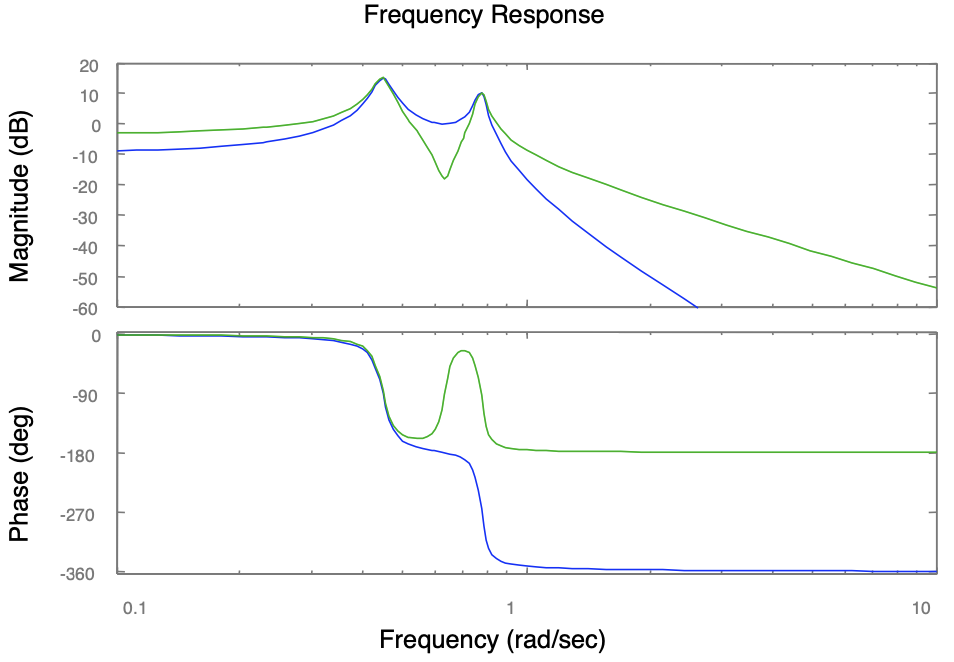

*Figure 2. Frequency response of a damped spring-mass system.*

m = 250; m1 = m; m2 = m; % masses (all equal)
k = 50; k1 = k; k2 = k; k3 = k; % spring constants
c = 10; % damping

A=[0,0,1,0;
0,0,0,1;
-(k1+k2)/m1, k2/m1,0,0;
k2/m2, -(k2+k3)/m2, 0, -c/m2];
B=[0;0;0; k3/m2];

C_q1=[1,0,0,0]; %for q1

C_q2=[0,1,0,0]; %for q2

D=0;

[num,den]=ss2tf(A,B,C_q1,D);
[num2,den2]=ss2tf(A,B,C_q2,D);

Hq1u=tf(num,den)

Hq1u =
 
                    0.04
  -----------------------------------------
  s^4 + 0.04 s^3 + 0.8 s^2 + 0.016 s + 0.12
 
Continuous-time transfer function.
Model Properties


Hq2u=tf(num2,den2)

Hq2u =
 
               0.2 s^2 + 0.08
  -----------------------------------------
  s^4 + 0.04 s^3 + 0.8 s^2 + 0.016 s + 0.12
 
Continuous-time transfer function.
Model Properties


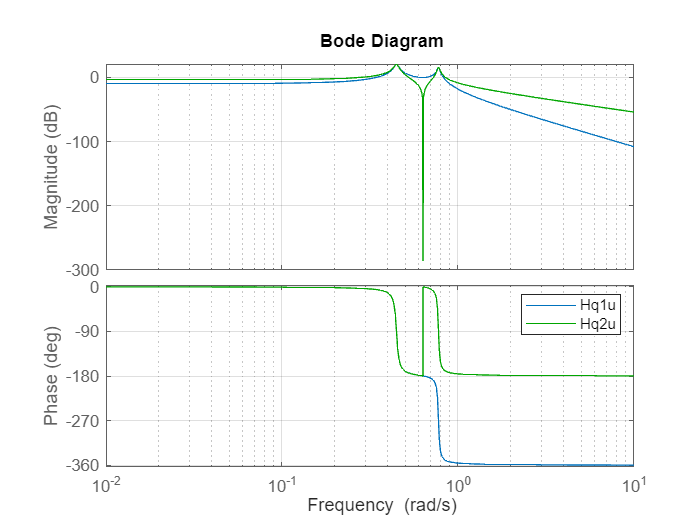

figure()
bode(Hq1u)
hold on
bode(Hq2u,'g')
grid on
legend('Hq1u','Hq2u')

 Compare the plotted bode diagram to Fig.2.

### 1.2 Difference Equations: Simulation of a Predator-Prey System

In some circumstances, it is more intuitive to describe the evolution of a system at discrete instants of time, denoted by an integer $k=0,1,2,\ldotp \ldotp \ldotp$, rather than continuously in time $t\in \mathbb{R}$. Similarly to the case of a model captured by differential equations, it is possible to choose as *state* of the system a set of variables containing the information about its past. We can, then, ask how the state of the system changes for each $k\ldotp$ Systems described in this manner are referred to as discrete-time systems and their evolution can be captured by means of *difference equations*:


$$x\left\lbrack k+1\right\rbrack =f\left(x\left\lbrack k\right\rbrack ,u\left\lbrack k\right\rbrack \right),$$



$$y\left\lbrack k\right\rbrack =h\left(x\left\lbrack k\right\rbrack ,u\left\lbrack k\right\rbrack \right)\ldotp$$


where $x\left\lbrack k\right\rbrack \in {\mathbb{R}}^n$is the state, $u\left\lbrack k\right\rbrack \in {\mathbb{R}}^p \;$is the input and $y\left\lbrack k\right\rbrack \in {\mathbb{R}}^{q\;} \;$is the output. In a nutshell, difference equations model discrete transitions between continuous variables, telling us how $x\left\lbrack k+1\right\rbrack \;$differs from $x\left\lbrack k\right\rbrack$. 

As an example of a discrete-time system which can be represented by difference equation we consider the predator-prey dynamics. The predator-prey problem refers to an ecological system involving two species, one of which feeds on the other, which can be modeled by tracking birth and death rates. Denoting with $H$ the population of hares, and with $L$ the population of lynxes,  Lotka-Volterra equations can be used to monitor the system at specific intervals of time $k$:


$$H\left\lbrack k+1\right\rbrack =H\left\lbrack k\right\rbrack +b_r \left(u\right)H\left\lbrack k\right\rbrack -a\;L\left\lbrack k\right\rbrack H\left\lbrack k\right\rbrack ,$$



$$L\left\lbrack k+1\right\rbrack =L\left\lbrack k\right\rbrack +c\;L\left\lbrack k\right\rbrack H\left\lbrack k\right\rbrack -d_f L\left\lbrack k\right\rbrack ,$$


where $b_r \left(u\right)$ is the hare birth rate as a function of food supply $u\left\lbrack k\right\rbrack$, $d_f$ is lynx mortality rate, $a$ and $c$ are interaction coeffcients, $u\left\lbrack k\right\rbrack$is the (optional) hare food and the output is the number of hare and lynxes. With this model, we can answer questions such as "Given the current population of predators and preys, and assuming no changes in the food supply of the prey species, what will it be next year?", "What happens if we change the food supply of the prey species?". 

**Task 5.** The function [constantsupply](matlab:open('./constantsupply.m')) implements the model of the predator-prey system with constant food supply. Study the function. Simulate the dynamics with constant food supply.

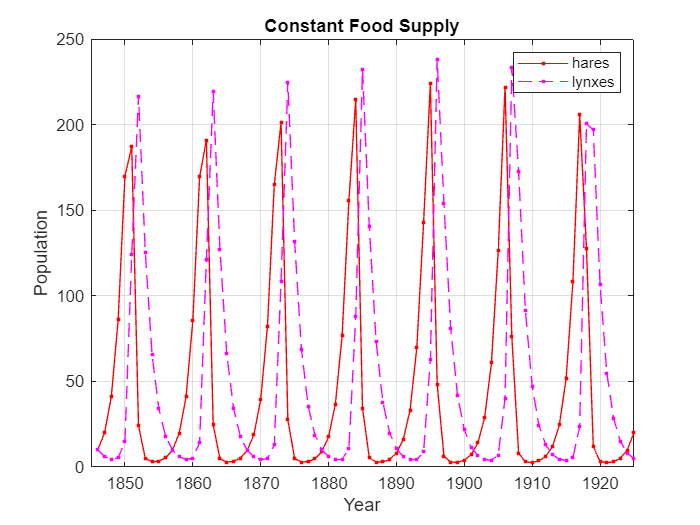

constantsupply

**Task 6.** The function [varyingsupply](matlab:open('./varyingsupply.m')) implements the model of the predator-prey system with varying food supply. Study the function. Experiment with different values of A and ω. Plot the responses after the transients have died out.

- **Trial 1:**

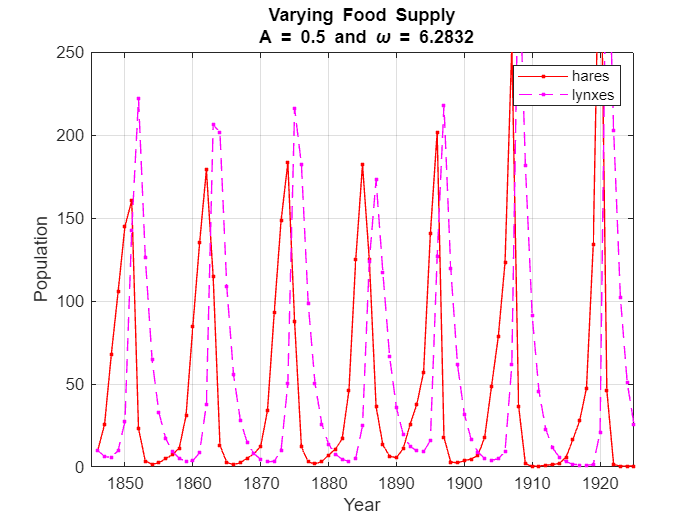

A_sup = 0.5;
omega_sup =  2*pi;
varyingsupply(A_sup,omega_sup)

- **Trial 2:**

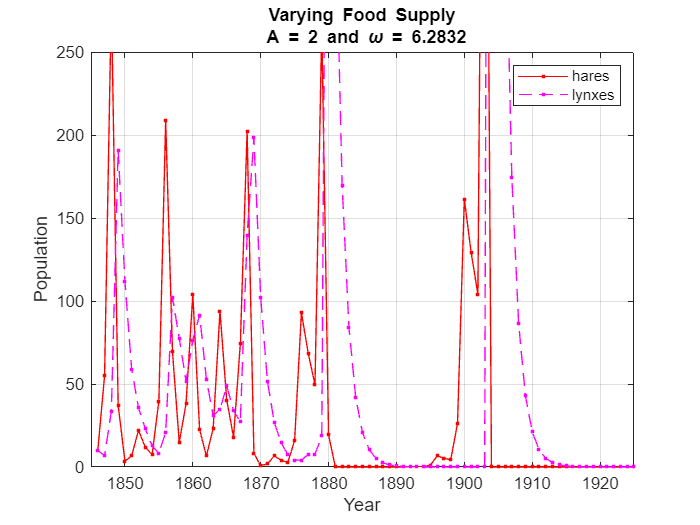

A_sup = 2;
omega_sup =  2*pi;
varyingsupply(A_sup,omega_sup)

- **Trial 3:**

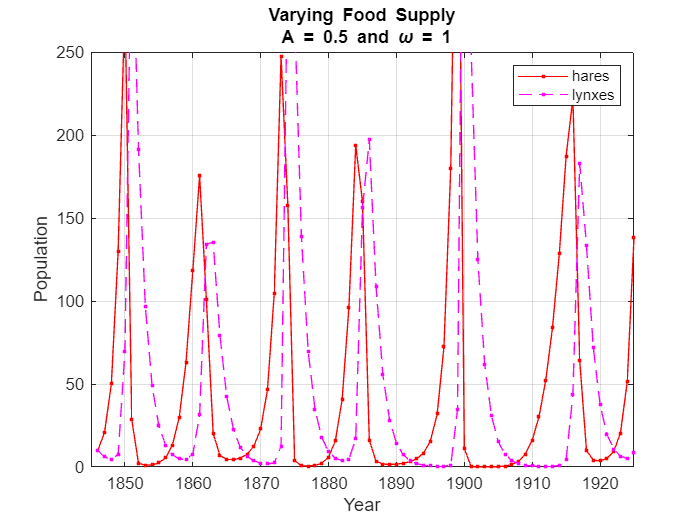

A_sup = 0.5;
omega_sup =  1;
varyingsupply(A_sup,omega_sup)

## **2. The Magic of Feedback**

Merraim-Webster defines feedback as "the return to the input of a part of the output of a machine, system, or process (as for producing changes in an electronic circuit that improve performance or in an automatic control device that provide self-corrective action)". The term refers to the mutual interconnection of two (or more) dynamical systems such that each system influences the other and their dynamics are thus strongly coupled, making simple causal reasoning about feedback systems difficult. Feedback is ubiquitous in both natural and engineered systems.

When applied to the control of systems, feedback has many interesting and useful properties. It makes it possible to design precise systems from imprecise components and to make relevant quantities in a system change in a prescribed fashion. Using feedback, an unstable system can be stabilized, and the effects of external disturbances can be reduced. In this homework, we present an example of a typical feedback mechanism: the system for controlling the speed of a vehicle, i.e., the cruise control of a car.

### **2.1 Cruise Control**

The cruise control system of a car aims to keep a steady velocity despite disturbances mainly due to varying road inclines. The controller compensate for these uncertainties by monitoring the vehicle's speed and adjusting the throttle accordingly. The system is modelled in the block diagram shown in Fig. 3 (see also Sec. 4.1 of the book "Feedback Systems: an Introduction for Scientists and Engineers, Second Edition", by KJ Åström and RM Murray). In the diagram, $v$ represents the car's speed, while $v_r$ denotes the desired (reference) speed. The controller, usually of a proportional-integral (PI) type, processes the signals $v$ and $v_r$ and produces a control signal $u$, which is sent to an actuator managing the throttle position. The throttle, then, regulates the engine's torque $T$, which is transmitted through the gears and wheels, generating a force $F$ that propels the car. Disturbance forces $F_d$ arise from changes in road slope, rolling resistance, and aerodynamic forces. Additionally, the cruise controller includes a human-machine interface, enabling the driver to set and adjust the desired speed. A mathematical model representing a simple cruise control system is detailed in Sec. 4.1 of the book by Åström and Murray.

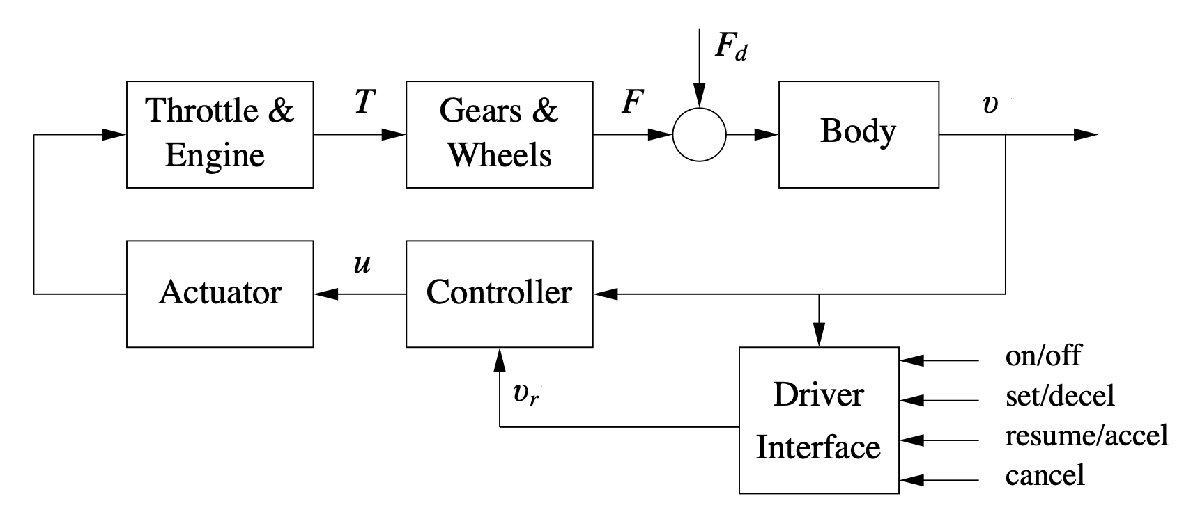

*Figure 3. Block diagram of a cruise control system for a car.*

The file `cruise_control_model` contains the above cited model implemented in Simulink. There is a PI controller with proportional gain $k_p$ and integral gain $k_i$. The reference signal is a step in the speed of amplitude $10\;$ [m/s] at time $t=20$ [s]. The car encounters a sloping road of $4^{\circ }$.

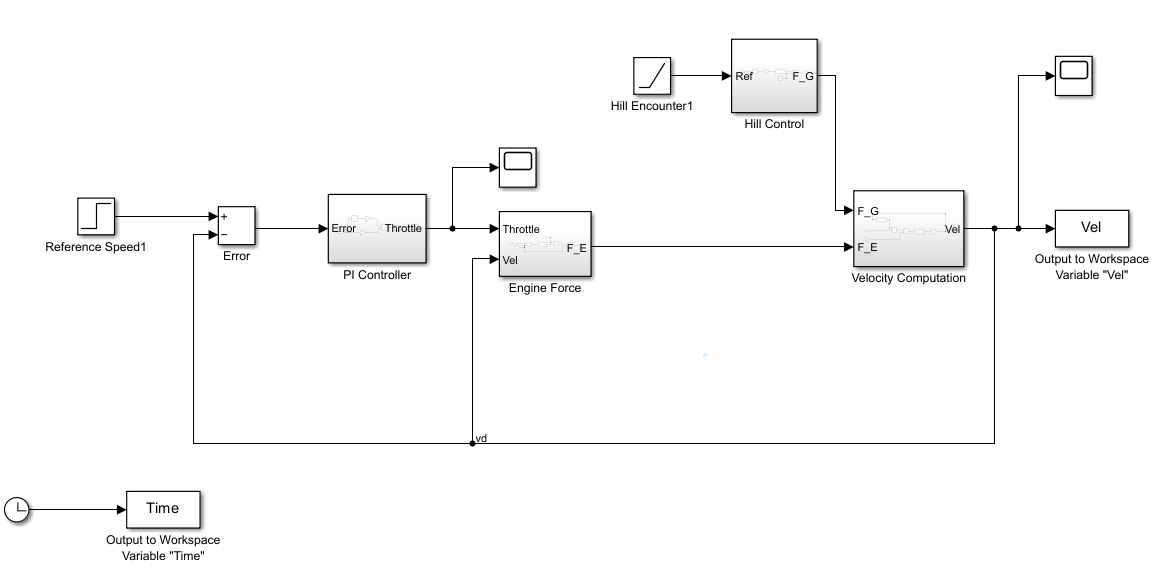

*Figure 4. Simulink model of cruise control.*

Open `cruise_control_model:`

open_system('cruise_control_model')

**Task 7.** Using stop time $T=250$ [s], $k_p =0\ldotp 5$, and $k_i$= 0.1, plot the vehicle’s speed as a function of time for  $m=1000$ [kg], $m=2000$ [kg] and $m=3000$ [kg], where $m$ indicates the total mass of the car, including passengers. The function [plotvel](matlab:open('./plotvel.m')) is responsible for running the Simulink file `cruise_control_model, `plotting the vehicle’s speed as a function of time and showing an animation representation. For more information about the animation, visit the [cruise control virtual lab](https://www.mathworks.com/matlabcentral/fileexchange/100064-virtual-hardware-and-labs-for-controls).

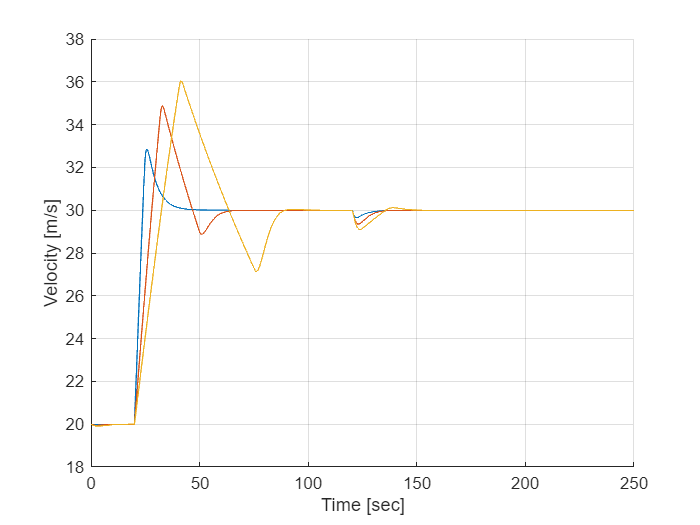

T = 250; % Stop Time in seconds
kp = 0.5; % Proportional gain
ki = 0.1; % Integral gain
m = 3000; % Mass in [kg]
hold on %Choose 'hold on' to plot on same figure, or 'figure;clf' to reset figure
plotvel(T, ki, kp, m);

**Task 8.** Using trial and error, change the parameters of the control law so that the overshoot in speed is not more than $1$ [m/s] for a vehicle with mass $m=1000$ [kg]. Hint: Clicking on plot with show more details.

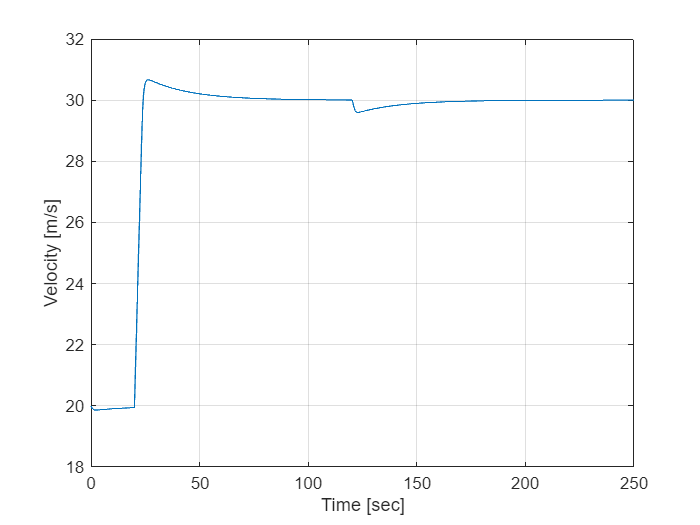

m = 1000; % Mass in [kg]
kp = 0.5; % Proportional gain
ki = 0.025; % Integral gain
plotvel(T, ki, kp, m);

**Task 9.** By manually tuning the control gains, design a controller that settles 50% faster than the default controller. Include the gains you used and a plot of the closed-loop response.

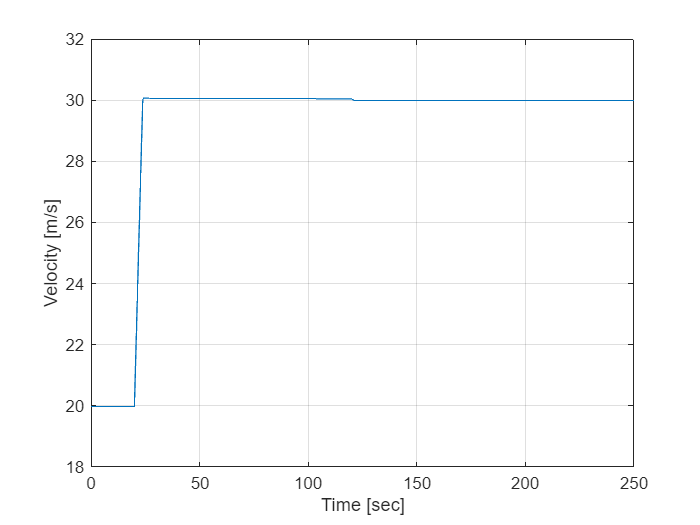

kp = 5; % Proportional gain
ki = 0.025; % Integral gain
plotvel(T, ki, kp, m);

Describe any undesireable features in the solution you obtain.

**Task 10.** Can you design a constant parameter control that will work well both masses $m=1000$ [kg] and $m=2000$ [kg]?

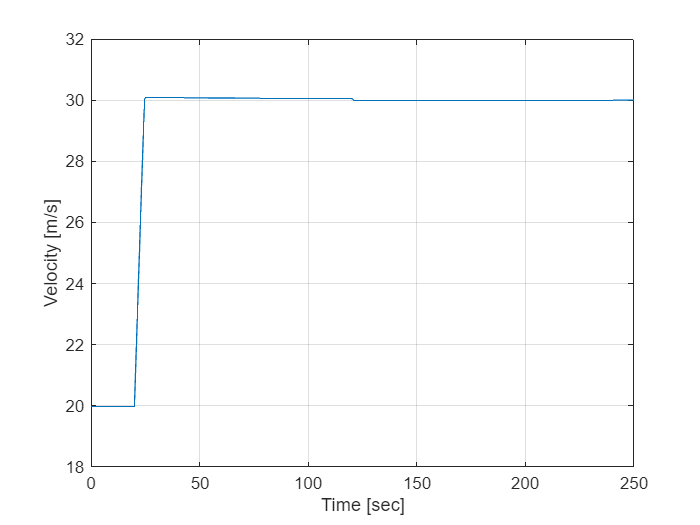

m = 1200; % Mass in [kg]
kp = 5; % Proportional gain
ki = 0.025; % Integral gain
plotvel(T, ki, kp, m);